% xy평면에서 말고 xyz평면에서 HS가 그려져야 함
clear all; clc;
HS=[0 0 20;0 30 20;0 15 20;15 15 20;15 0 20;15 30 20;40 30 20;20 30 20;20 15 20;40 15 20;40 0 20;20 0 20]; 
    % H좌표                                          40 여기서 부터 S좌표
H=[0 0 0 15 15 15;0 30 15 15 0 30;20 20 20 20 20 20];
% H에서 S로 옮겨갈때와 S를 그릴때 H를 유지시켜야 하므로(clf때문에 지워지니까) 변수 H를 통해 H를 계속 그려준다
d=[0 5 5 0 -5 5 0 -5 -5 0 5 -5 0;
    0 -5 5 0 5 5 0 5 -5 0 -5 -5 0;
    20 0 0 20 0 0 -20 0 0 -20 0 0 20;
    1 1 1 1 1 1 1 1 1 1 1 1 1]; % 정팔면체 x1,x2,x3,평행이동을 위한 가상의 x4(1이 13개인 이유)

p=[1 2 3;4 5 6;5 6 7;8 9 10;9 10 11;11 12 13;1 8 9;2 3 7]; % 팔면체에 있는 삼각형 8개. 그 삼각형들을 이루고 있는 좌표들이다
c=['b';'r';'g';'w';'k';'c';'m';'y']; % 팔면체 색깔 8개 1면에 1색

orbit=[0,0,20]; % 처음 궤도는 H시작점인 0,0,20에서부터 시작한다
noRot1=2; % 한 획을 그을때 팔면체가 몇 바퀴 도는지. -> 한 획당 팔면체의 자전 회수

t1=0;t2=0;t3=0; % t1은 x1축 좌표의 변화량을 누적하여 가장 최근까지 평행이동한 좌표의 위치를 기억한다.
                % 그곳에서부터 이어지도록 그려야하기 때문(t2 -> x2,t3 -> x3 도 마찬가지)

vaz=30;vel=90; % viewpoint 방위각, 고도, 후에 for문에서 바뀌는 변수값에 따라 viewpoint가 같이 연속적으로 변한다
               % viewpoint 초기값은 방위각 : 30, 고도 90으로 설정했다.

for j=1:11 % 총 11획을 그을 것이므로(크게 H->S 좌표 이동하는 경우, 이 for문에서 H 또는 S를 그리는 경우 2가지로 나뉜다)
    tempHS=HS(j+1,:)-HS(j,:) % 다음획의 좌표 - 현재 획의 좌표 (+surge? -surge? +sway? -sway? 4가지 경우의 수가 있다 x1x2평면에서 HS를 그릴 것이기 때문)
    neg=0; % 다음획의 좌표 - 현재 획의 좌표 변화량이 음수인지 양수인지 구별해주는(기억해주는) 변수
    x1=0;x2=0; % x1, x2값 초기화 -> surge, sway운동 후 그 다음 획을 그을 것이기 때문에 초기화가 필요하다

    if(j==6) % j가 6일때는 S를 그리려고 사면체가 H의 마지막 좌표에서 S 첫번째 좌표로 이동하는 모션이다
        diff_len=tempHS(1,1); % surge운동을 할 것이므로 S그릴 때 첫좌표 - H그릴 때 마지막 좌표를 빼서 그 만큼 x1축 평행이동을 한다(surge==+diff_len)
        if(diff_len<0) % diff_len을 크기로 만들것이다. 따라서 음수면 양수로 만들고 변화량이 음수였다는 것을 기억하기 위해 neg라는 변수에 1을 저장한다
                neg=1; % 변화량이 음수였다. == -surge운동 또는 -sway운동을 했다
                diff_len=abs(diff_len); % 음수를 양수로 만들어 그만큼의 평행이동을 시킬 것이므로 음수라면 양수로 만든다
        end 
        for x1=0:0.5:diff_len % x1축 방향으로 20만큼 surge (자전만 하면서)
             clf; psi=noRot1*2*pi*x1/diff_len;
             if(neg) 
                    Rz=[cos(psi) -sin(psi) 0  t1-x1;
                    sin(psi) cos(psi)  0  t2;
                    0         0        1  t3;
                    0         0        0  1];
             else
                    Rz=[cos(psi) -sin(psi) 0  t1+x1;
                    sin(psi) cos(psi)  0  t2;
                    0         0        1  t3;
                    0         0        0  1];
             end
            
             y=Rz*d; % 팔면체 도형을 x1만큼 surge함 -> y에 저장
             line(H(1,:),H(2,:),H(3,:),'Linewidth',2); % 이전에 그린 H는 계속 유지시켜야 하니까 H를 계속 그려준다

             % 팔면체에 있는 삼각형들 각각에 색깔 입혀주는 for문
             for i=1:1:8 
                 patch([y(1,p(i,1)) y(1,p(i,2)), y(1,p(i,3))],[y(2,p(i,1)) y(2,p(i,2)), y(2,p(i,3))],[y(3,p(i,1)) y(3,p(i,2)), y(3,p(i,3))],c(i));
             end
             % 그래프 형식 그려주는 코드 4줄(좌표축 이름, 나타내는 범위, 변하는 viewpoint(방위각,고도 이용))
             xlabel('x1-axis');ylabel('x2-axis');zlabel('x3-axis');
             axis([-10 100 -40 80 -20 40]);
             vaz=vaz-0.08*x1;vel=vel+0.05*x1;view(vaz,vel); grid;
             pause(0.000001);
         end
            orbit=[40,30,20]; % 이제 S의 첫번째 좌표로 옮겨졌으면 팔면체의 궤적은 다시(40,30,20)부터 시작할 것이다
    else  % H 또는 S를 그릴 경우 
        if(tempHS(1,1)~=0) % x1축에서의 평행이동이 있었으면
            diff_len=tempHS(1,1);
            if(diff_len<0) 
                neg=1;
                diff_len=abs(diff_len); % 길이 차이의 크기만 저장(양수) for문 돌리기 위해
            end
            for x1=0:0.5:diff_len % x1축 방향으로 x1변화량만큼 이동 (2바퀴 자전==yaw운동을 하면서)
            clf;psi=noRot1*2*pi*x1/diff_len;
            if(neg) 
                Rz=[cos(psi) -sin(psi) 0  t1-x1;
                sin(psi) cos(psi)  0  t2;
                0         0        1  t3;
                0         0        0  1];
            else
                Rz=[cos(psi) -sin(psi) 0  t1+x1;
                sin(psi) cos(psi)  0  t2;
                0         0        1  t3;
                0         0        0  1];
            end
            y=Rz*d; % 팔면체 도형을 x1만큼 surge함(2바퀴 자전, yaw운동 하면서) -> y에 저장
            if(j>6) % H를 다 그린 후 S를 그릴 때는
                    line(H(1,:),H(2,:),H(3,:),'Linewidth',2); % clf로 인하여 H가 없어지면 안되니까 H를 계속 그려준다
            end
            line([y(1,:) y(1,1)],[y(2,:) y(2,1)],[y(3,:) y(3,1)]); % 팔면체를 그려준다 
            orbit=[orbit;y(1,1) y(2,1) y(3,1)]; % 팔면체가 이동하면서 팔면체 꼭지점의 x1,x2,x3 좌표들을 저장하며 궤도를 최신화한다.
            line(orbit(:,1),orbit(:,2),orbit(:,3),'Linewidth',2); % 최신화된 궤도로 line을 이용하여 선을 그려 획을 긋는 모션을 구현한다.

            % 팔면체 도형에 색깔 입혀주는 for문
            for i=1:1:8 
                patch([y(1,p(i,1)) y(1,p(i,2)), y(1,p(i,3))],[y(2,p(i,1)) y(2,p(i,2)), y(2,p(i,3))], [y(3,p(i,1)) y(3,p(i,2)), y(3,p(i,3))],c(i));
            end
            % 그래프 형식 그려주는 코드 3줄
            xlabel('x1-axis');ylabel('x2-axis');zlabel('x3-axis');axis([-10 100 -40 80 -20 40]);
            vaz=vaz-0.08*x1;vel=vel+0.05*x1;view(vaz,vel); grid;
            pause(0.000001);
            end
        elseif(tempHS(1,2)~=0) % x2축에서의 평행이동이 있었으면
            diff_len=tempHS(1,2);
            if(diff_len<0) 
                neg=1;
                diff_len=abs(diff_len); % 길이 차이의 크기만 저장(양수) for문 돌리기 위해
            end 
            for x2=0:0.5:diff_len % x2축 방향으로 x2변화량만큼 이동 (2바퀴 자전==yaw운동을 하면서)
                clf; psi=noRot1*2*pi*x2/diff_len;
                if(neg) 
                    Rz=[cos(psi) -sin(psi) 0 t1;
                    sin(psi) cos(psi)  0  t2-x2;
                    0         0        1  t3;
                    0         0        0  1];
                else
                    Rz=[cos(psi) -sin(psi) 0  t1;
                    sin(psi) cos(psi)  0  t2+x2;
                    0         0        1  t3;
                    0         0        0  1];
                end
                y=Rz*d; % 팔면체 도형을 x2만큼 sway함(2바퀴 자전, yaw운동 하면서) -> y에 저장
                
                if(j>6) % H를 다 그린 후 S를 그릴 때는
                    line(H(1,:),H(2,:),H(3,:),'Linewidth',2); % clf로 인하여 H가 없어지면 안되니까 H를 계속 그려준다
                end
                line([y(1,:) y(1,1)],[y(2,:) y(2,1)],[y(3,:) y(3,1)]); % 팔면체를 그려준다 
                orbit=[orbit;y(1,1) y(2,1) y(3,1)]; % 꼭지점 자취 최신화
                line(orbit(:,1),orbit(:,2),orbit(:,3),'Linewidth',2); % 꼭지점 좌취대로 계속 그려준다

                % 팔면체 도형에 색깔 입혀주는 for문
                for i=1:1:8 
                    patch([y(1,p(i,1)) y(1,p(i,2)), y(1,p(i,3))],[y(2,p(i,1)) y(2,p(i,2)), y(2,p(i,3))],[y(3,p(i,1)) y(3,p(i,2)), y(3,p(i,3))],c(i));
                end
                % 그래프 형식 그려주는 코드 4줄
                xlabel('x1-axis');ylabel('x2-axis');zlabel('x3-axis');axis([-10 100 -40 80 -20 40]);
                vaz=vaz-0.08*x2;vel=vel-0.05*x2;view(vaz,vel); grid;
                pause(0.000001);
            end
        end 
    end
    if(neg) % 좌표 변화량이 음수이면 가장 최신의 평행이동한 좌표에서 그 변화량만큼 빼준다(평행이동 현황 최신화)
        t1=t1-x1;
        t2=t2-x2;
    else % 좌표 변화량이 양수이면 가장 최신의 평행이동한 좌표에서 그 변화량만큼 더한다(평행이동 현황 최신화)
        t1=t1+x1;
        t2=t2+x2;
    end
end

tempHS =      0    30     0


tempHS =      0   -15     0


tempHS =     15     0     0


tempHS =      0   -15     0


tempHS =      0    30     0


tempHS =     25     0     0


tempHS =    -20     0     0


tempHS =      0   -15     0


tempHS =     20     0     0


tempHS =      0   -15     0


tempHS =    -20     0     0


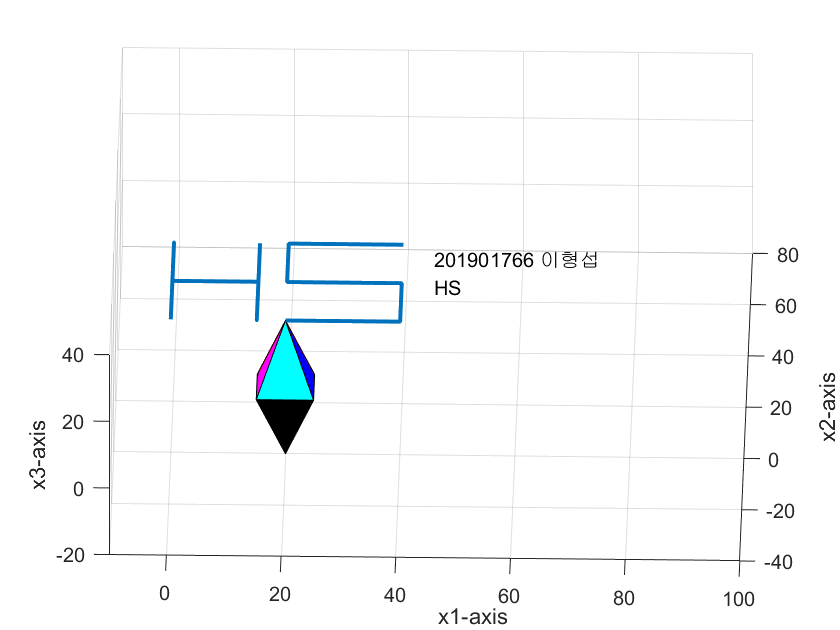

text(45,45,'201901766 이형섭\newlineHS')